# Multilevel List

This example shows two ways to create multilevel lists. The first way creates a cell array that models a multilevel list and appends the cell array to the document. The second way programmatically builds up the multilevel list by constructing List and ListItem objects.

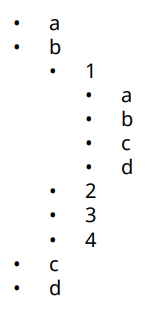

## Setup

Import the DOM packages so that you do not have to use the fully qualified class names.

import mlreportgen.dom.*

## Cell Array List

### Simple List

A simple list can be represented as a simple cell array where cell array elements are used to create list items. To create this simple list:

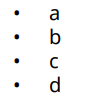

Create this cell array.

simpleCellArray = { ...
    'a', ...
    'b', ...
    'c', ...
    'd'};

Append the cell array to a `Document` object. To create an HTML report, replace "pdf" with "html". To create a Word report, replace "pdf" with "docx". 

d = Document("cell_simple_list", "pdf");
append(d, simpleCellArray);
close(d);
rptview(d);

### Two-Level List

A two-level list can be represented as a cell array where one or more elements are cells. To create this two-level list:

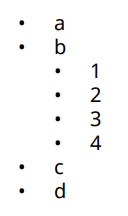

Create this cell array:

twoLevelCellArray = { ...
    'a', ...
    'b', ...
    { ...
        '1', ...
        '2', ...
        '3', ...
        '4' ...
    }, ...
    'c', ...
    'd'};        

Append the two-level cell array to a `Document` object. To create an HTML report, replace "pdf" with "html". To create a Word report, replace "pdf" with "docx". 

d = Document("cell_two_level_list", "pdf");
append(d, twoLevelCellArray);
close(d);
rptview(d);

### Three Level List

A three-level list can be represented as a nested cell array that is three levels deep. To create this three-level list:

Create this cell array:

threeLevelCellArray = {
    'a', ...
    'b', ...
    { ...
        '1', ...
        { ...
            'a', ...
            'b', ...
            'c', ...
            'd' ...
        }, ...
        '2', ...
        '3', ...
        '4' ...
    }, ...
    'c', ...
    'd'};

Append the three-level cell array to a `Document` object. To create an HTML report, replace "pdf" with "html". To create a Word report, replace "pdf" with "docx". 

d = Document("cell_three_level_list", "pdf");
append(d, threeLevelCellArray);
close(d);
rptview(d);

To create even deeper multi-level lists, add more nested cell arrays to represent inner lists.

## Programmatic List

### Simple List

A simple list can be constructed by creating `ListItem` objects and appending them to an OrderedList or UnorderedList object.  For the following simple unordered list:

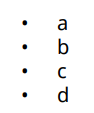

Create `ListItem` objects.

itemA = ListItem('a');
itemB = ListItem('b');
itemC = ListItem('c');
itemD = ListItem('d');

Append the `ListItem` objects to an `UnorderedList` object.

unorderedList = UnorderedList();
append(unorderedList, itemA);
append(unorderedList, itemB);
append(unorderedList, itemC);
append(unorderedList, itemD);

Append the list to a `Document` object. To create an HTML report, replace "pdf" with "html". To create a Word report, replace "pdf" with "docx". 

d = Document("prog_simple_list", "pdf");
append(d, unorderedList);
close(d);
rptview(d);

### Two-Level List

A two-level list can be constructed by appending either an `OrderedList` or an `UnorderedList` object to the parent L`ist` Object. For the following two-level list:

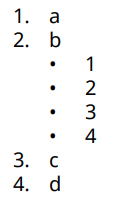

Create a second level unordered list by using a cell array. To create an HTML report, replace "pdf" with "html". To create a Word report, replace "pdf" with "docx". For Word report, mixing unordered and ordered lists may not produce the best results. See the custom styled word list example.

secondLevelList = UnorderedList({ ...
    '1', ...
    '2', ...
    '3', ...
    '4'});

Create first level list.

itemA = ListItem('a');
itemB = ListItem('b');
itemC = ListItem('c');
itemD = ListItem('d');

firstLevelList = OrderedList();
append(firstLevelList, itemA);
append(firstLevelList, itemB);
append(firstLevelList, secondLevelList); % Not a ListItem, but an OrderedList
append(firstLevelList, itemC);
append(firstLevelList, itemD);

Append the list to a `Document` object.

d = Document("prog_two_level_list", "pdf");
append(d, firstLevelList);
close(d);
rptview(d);

### Three-Level List

A three-level list can be constructed by appending a two-level list to the parent `List` Object.  For the following three-level list:

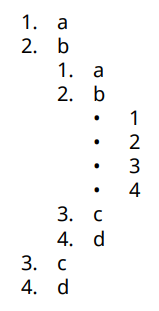

Create the third-level list.

thirdLevelList = UnorderedList({ ...
    '1', ...
    '2', ...
    '3', ...
    '4'});

Create the second-level list.

secondLevelList = OrderedList({ ...
    'a', ...
    'b', ...
    thirdLevelList, ... % This is a List, the rest are ListItems.
    'c', ...
    'd'});

Create the first-level list.

firstLevelList = OrderedList({ 
    'a', ...
    'b', ...
    secondLevelList, ...
    'c', ...
    'd'});

Append the list to a `Document` object. To create a Word report, replace "pdf" with "docx". To create an HTML report, replace "pdf" with "html". For Word report, mixing unordered and ordered lists may not produce the best results. See the custom styled word list example.

d = Document("prog_three_level_list", "pdf");
append(d, firstLevelList);
close(d);
rptview(d);

To create even deeper multilevel lists, append `List` objects to `List` objects.

*Copyright 2019 The MathWorks, Inc.*